# Euler Bernoulli beam with cubic spring and damper

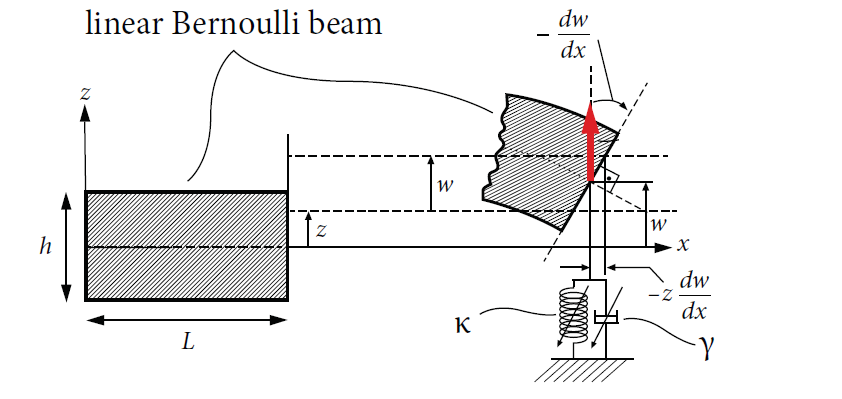

Instead of external excitation on the last node, the excitation here is of parametric type. The tip of the beam is subject to linear parametric excitation. The experiment this example is based on can be found in 

Chen, C. C. & Yeh, M. K.:  *Parametric instability of a beam under electromagnetic excitation*. Journal of Sound and Vibration 240,747–764, [https://doi.org/10.1006/jsvi.2000.3255](https://doi.org/10.1006/jsvi.2000.3255) 

clear all

## Generate model

nElements = 5;
kappa = 50; % cubic spring
gamma = 0.01; % cubic damping
sigmas = [10,20,30,40]; % Damping coefficients


ii = 1;
for sigma = sigmas
    [M,C,K,fnl,fext] = build_model_parametric(kappa, gamma, nElements);
    C = sigma * C;
    n = length(M);

## Dynamical system setup 

We consider the parametrically excited system


$$\mathbf{M}\ddot{\mathbf{x}}+\mathbf{C}\dot{\mathbf{x}}+\mathbf{K}\mathbf{x}+\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})=\epsilon\mathbf{g}(\mathbf{x},\dot{\mathbf{x}},\Omega t),$$


which can be written in the first-order form as 


$$\mathbf{B}\dot{\mathbf{z}}	=\mathbf{Az}+\mathbf{F}(\mathbf{z})+\epsilon\mathbf{G}(\mathbf{z},\phi),\\\dot{\mathbf{\phi}}	
=\mathbf{\Omega}$$


where


$$\mathbf{z}=\left[\begin{array}{c}\mathbf{x}\\\dot{\mathbf{x}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}-\mathbf{K} 
& \mathbf{0}\\\mathbf{0} & \mathbf{M}\end{array}\right],\mathbf{B}=\left[\begin{array}{cc}\mathbf{C} 
& \mathbf{M}\\\mathbf{M} & \mathbf{0}\end{array}\right],\quad\quad\mathbf{F}(\mathbf{z})=\left[\begin{array}{c}\mathbf{-\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})}\\\mathbf{0}\end{array}\right],\quad\mathbf{G}(\mathbf{z},\mathbf{\phi})=\left[\begin{array}{c}
\mathbf{g}(\mathbf{x, \dot{x}},\phi)\\
\mathbf{0}
\end{array}\right]$$


DSorder = 2;
DS = DynamicalSystem(DSorder);
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',5,'Nmax',10,'notation','multiindex')
epsilon = 0.002;
DS.add_forcing(fext,epsilon);

## Linear Modal Analysis 

% Analyse spectrum
[V,D,W_evec] = DS.linear_spectral_analysis();


#### Choose Master subspace (perform resonance analysis)

% Set up SSM object
S = SSM(DS);
set(S.Options, 'reltol', 0.3,'notation','multiindex')

%Choose Master subspace
resModes = [1,2];
S.choose_E(resModes);

## Stability Diagram from Reduced Dynamics

We extract the stability diagram using continuation of bifurcations. By extending the dynamical system


$$\mathbf{B}\dot{\mathbf{z}}	=\mathbf{Az}+\mathbf{F}(\mathbf{z})+\epsilon\mathbf{G}(\mathbf{z},\phi)$$


 to an autonomous system of variables $(\mathbf{z}, \tau) \in \mathbb{R}^N \times S^1$ the trivial fixed point $\mathbf{z} =\mathbf{0}$ of the paremtrically excited system can be interpreted as the periodic orbit $(\mathbf{z}, \tau ) = (\mathbf{0}, t \ \text{mod} \ 2\pi )$ . Any change of the stability behaviour of this periodic orbit is then given by some bifurcation. At the stability boundary of the principal resonance with $\Omega \approx 2 \omega_0$ nontrivial periodic orbits with response period $T = 4 \pi / \Omega$ emerge. If continuation of $2 \pi / \Omega$ periodic orbits is used then these bifurcations show up as period doubling ('PD') bifurcations. Initially continuing $4 \pi / \Omega$ periodic orbits leads to a saddle node ('SN') bifurcation. The function extract_Stability_Diagram allows to chose between these two options for constructing the stability diagram.

### Settings

set(S.contOptions,'PtMX',50,'bi_direct',true)
set(S.FRCOptions,'branchSwitch',true)
PlotSD = false;
order  = 3;


### Initial condition and parameter range


omega0 = imag(S.E.spectrum(1));
p0 = [2*omega0,0.1]; % Initial condition
 
OmegaRange =[13,15];
epRange = [0,1];


### Computation

startSDSSM = tic;
SD = S.extract_Stability_Diagram(resModes, order, OmegaRange,epRange,'amp', p0,'PD',PlotSD);
timings(ii).SDSSM = toc(startSDSSM);

## Verification: Collocation using [coco](https://sourceforge.net/p/cocotools/wiki/Home/)

Dankowicz, H., & Schilder, F. (2013).  *Recipes for Continuation,* SIAM Philadelphia. [<https://doi.org/10.1137/1.9781611972573](https://doi.org/10.1137/1.9781611972573)>

nCycles = 10;
coco_sd = cocoWrapper(DS, nCycles, []);
set(coco_sd.Options, 'PtMX',100, 'bi_direct',true,'NAdapt',0);
set(coco_sd,'branchSwitch',true)

startcoco = tic;
SD_full = coco_sd.extract_Stability_Diagram(OmegaRange,epRange,'amp',p0,'PD',PlotSD);
timings(ii).cocoFRC = toc(startcoco);

% Save results 
name = strcat('SD_damp',num2str(sigma),'n',num2str(2*nElements));
save(name, 'SD','SD_full')
ii = ii + 1;
end

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 8.840017e-03
modal damping ratio for 2 mode is 5.488086e-02
modal damping ratio for 3 mode is 1.541080e-01
modal damping ratio for 4 mode is 3.044305e-01
modal damping ratio for 5 mode is 5.052761e-01

 The first 10 eigenvalues are given as 
   1.0e+02 *

  -0.0006 + 0.0700i
  -0.0006 - 0.0700i
  -0.0241 + 0.4383i
  -0.0241 - 0.4383i
  -0.1900 + 1.2181i
  -0.1900 - 1.2181i
  -0.7414 + 2.3198i
  -0.7414 - 2.3198i
  -2.0424 + 3.4882i
  -2.0424 - 3.4882i



No (near) outer resonances detected in the (truncated) spectrum
sigma_out = 3300
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0619 + 7.0003i
  -0.0619 + 7.0003i
  -0.0619 + 7.0003i
  -0.0619 + 7.0003i
  -0.0619 - 7.0003i
  -0.0619 - 7.0003i
  -0.0619 - 7.0003i
  -0.0619 - 7.0003i

sigma_in = 3300


No (near) outer resonances detected in the (truncated) spectrum
sigma_out = 3300
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0619 + 7.0003i
  -0.0619 + 7.0003i
  -0.0619 + 7.0003i
  -0.0619 + 7.0003i
  -0.0619 - 7.0003i
  -0.0619 - 7.0003i
  -0.0619 - 7.0003i
  -0.0619 - 7.0003i

sigma_in = 3300
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 1.52E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 2.10E-02 MB

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          0.00e+00  1.40e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE           eps    po.period
  


 Run='full_detect_bif': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          0.00e+00  1.98e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE           eps           om
    0  00:00:02   1.9805e+01      1  EP      1.0000e-01   1.4001e+01
    2  00:00:04   1.9805e+01      2  EP      6.9389e-18   1.4001e+01

 STEP      TIME        ||U||  LABEL  TYPE           eps           om
    0  00:00:05   1.9805e+01      3  EP      1.0000e-01   1.4001e+01
    2  00:00:10   1.9807e+01      4  PD      2.0821e-01   1.4001e+01
    5  00:00:13   1.9855e+01      5  EP      1.0000e+00   1.4001e+01

 Run='full_family_bif_1': Continue bifurcations from point 4 in run 'full_detect_bif'.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0  

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 1.768003e-02
modal damping ratio for 2 mode is 1.097617e-01
modal damping ratio for 3 mode is 3.082160e-01
modal damping ratio for 4 mode is 6.088610e-01
modal damping ratio for 5 mode is 1.010552e+00

 The first 10 eigenvalues are given as 
   1.0e+02 *

  -0.0012 + 0.0700i
  -0.0012 - 0.0700i
  -0.0482 + 0.4363i
  -0.0482 - 0.4363i
  -0.3800 + 1.1728i
  -0.3800 - 1.1728i
  -1.4828 + 1.9320i
  -1.4828 - 1.9320i
  -3.4961 + 0.0000i
  -4.6736 + 0.0000i



No (near) outer resonances detected in the (truncated) spectrum
sigma_out = 3776
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.1238 + 6.9995i
  -0.1238 + 6.9995i
  -0.1238 + 6.9995i
  -0.1238 + 6.9995i
  -0.1238 - 6.9995i
  -0.1238 - 6.9995i
  -0.1238 - 6.9995i
  -0.1238 - 6.9995i

sigma_in = 3776


No (near) outer resonances detected in the (truncated) spectrum
sigma_out = 3776
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.1238 + 6.9995i
  -0.1238 + 6.9995i
  -0.1238 + 6.9995i
  -0.1238 + 6.9995i
  -0.1238 - 6.9995i
  -0.1238 - 6.9995i
  -0.1238 - 6.9995i
  -0.1238 - 6.9995i

sigma_in = 3776
Manifold computation time at order 2 = 00:00:01
Estimated memory usage at order  2 = 1.52E-02 MB
Manifold computation time at order 3 = 00:00:01
Estimated memory usage at order  3 = 2.10E-02 MB

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          0.00e+00  1.40e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE           eps    po.period
  


 Run='full_detect_bif': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          0.00e+00  1.98e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE           eps           om
    0  00:00:02   1.9803e+01      1  EP      1.0000e-01   1.3999e+01
    2  00:00:04   1.9803e+01      2  EP      6.9389e-18   1.3999e+01

 STEP      TIME        ||U||  LABEL  TYPE           eps           om
    0  00:00:05   1.9803e+01      3  EP      1.0000e-01   1.3999e+01
    3  00:00:13   1.9811e+01      4  PD      4.1644e-01   1.3999e+01
    5  00:00:15   1.9853e+01      5  EP      1.0000e+00   1.3999e+01

 Run='full_family_bif_1': Continue bifurcations from point 4 in run 'full_detect_bif'.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0  

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.652005e-02
modal damping ratio for 2 mode is 1.646426e-01
modal damping ratio for 3 mode is 4.623240e-01
modal damping ratio for 4 mode is 9.132915e-01
modal damping ratio for 5 mode is 1.515828e+00

 The first 10 eigenvalues are given as 
   1.0e+03 *

  -0.0002 + 0.0070i
  -0.0002 - 0.0070i
  -0.0072 + 0.0433i
  -0.0072 - 0.0433i
  -0.0570 + 0.1093i
  -0.0570 - 0.1093i
  -0.1522 + 0.0000i
  -0.2224 + 0.0992i
  -0.2224 - 0.0992i
  -1.0732 + 0.0000i



No (near) outer resonances detected in the (truncated) spectrum
sigma_out = 5780
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.1857 + 6.9981i
  -0.1857 + 6.9981i
  -0.1857 + 6.9981i
  -0.1857 + 6.9981i
  -0.1857 - 6.9981i
  -0.1857 - 6.9981i
  -0.1857 - 6.9981i
  -0.1857 - 6.9981i

sigma_in = 5780


No (near) outer resonances detected in the (truncated) spectrum
sigma_out = 5780
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.1857 + 6.9981i
  -0.1857 + 6.9981i
  -0.1857 + 6.9981i
  -0.1857 + 6.9981i
  -0.1857 - 6.9981i
  -0.1857 - 6.9981i
  -0.1857 - 6.9981i
  -0.1857 - 6.9981i

sigma_in = 5780
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 1.52E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 2.10E-02 MB

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          0.00e+00  1.40e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE           eps    po.period
  


 Run='full_detect_bif': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          0.00e+00  1.98e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE           eps           om
    0  00:00:02   1.9799e+01      1  EP      1.0000e-01   1.3996e+01
    2  00:00:04   1.9799e+01      2  EP      6.9389e-18   1.3996e+01

 STEP      TIME        ||U||  LABEL  TYPE           eps           om
    0  00:00:05   1.9799e+01      3  EP      1.0000e-01   1.3996e+01
    4  00:00:15   1.9818e+01      4  PD      6.2474e-01   1.3996e+01
    5  00:00:16   1.9849e+01      5  EP      1.0000e+00   1.3996e+01

 Run='full_family_bif_1': Continue bifurcations from point 4 in run 'full_detect_bif'.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0  

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 3.536007e-02
modal damping ratio for 2 mode is 2.195234e-01
modal damping ratio for 3 mode is 6.164321e-01
modal damping ratio for 4 mode is 1.217722e+00
modal damping ratio for 5 mode is 2.021105e+00

 The first 10 eigenvalues are given as 
   1.0e+03 *

  -0.0002 + 0.0070i
  -0.0002 - 0.0070i
  -0.0096 + 0.0428i
  -0.0096 - 0.0428i
  -0.0760 + 0.0971i
  -0.0760 - 0.0971i
  -0.1070 + 0.0000i
  -0.1273 + 0.0000i
  -0.4658 + 0.0000i
  -1.5269 + 0.0000i



No (near) outer resonances detected in the (truncated) spectrum
sigma_out = 6168
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.2475 + 6.9962i
  -0.2475 + 6.9962i
  -0.2475 + 6.9962i
  -0.2475 + 6.9962i
  -0.2475 - 6.9962i
  -0.2475 - 6.9962i
  -0.2475 - 6.9962i
  -0.2475 - 6.9962i

sigma_in = 6168


No (near) outer resonances detected in the (truncated) spectrum
sigma_out = 6168
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.2475 + 6.9962i
  -0.2475 + 6.9962i
  -0.2475 + 6.9962i
  -0.2475 + 6.9962i
  -0.2475 - 6.9962i
  -0.2475 - 6.9962i
  -0.2475 - 6.9962i
  -0.2475 - 6.9962i

sigma_in = 6168
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 1.52E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 2.10E-02 MB

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          0.00e+00  1.40e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE           eps    po.period
  


 Run='full_detect_bif': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          0.00e+00  1.98e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE           eps           om
    0  00:00:02   1.9794e+01      1  EP      1.0000e-01   1.3992e+01
    2  00:00:06   1.9793e+01      2  EP      6.9389e-18   1.3992e+01

 STEP      TIME        ||U||  LABEL  TYPE           eps           om
    0  00:00:08   1.9794e+01      3  EP      1.0000e-01   1.3992e+01
    4  00:00:17   1.9828e+01      4  PD      8.3312e-01   1.3992e+01
    5  00:00:18   1.9844e+01      5  EP      1.0000e+00   1.3992e+01

 Run='full_family_bif_1': Continue bifurcations from point 4 in run 'full_detect_bif'.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0  

% Plot for paper
timings


timings =

     []



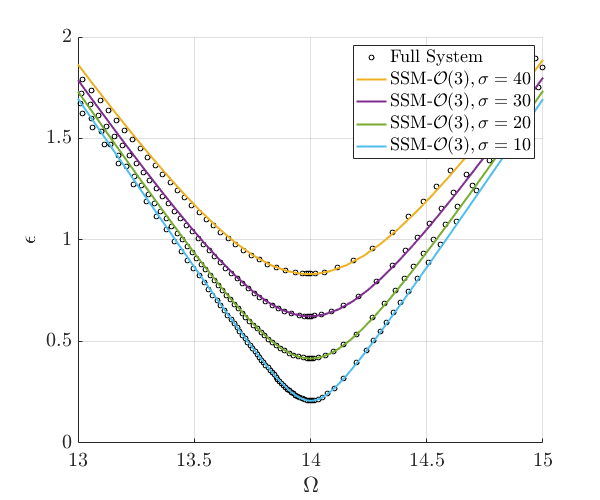

BBplotSD(nElements,sigmas); % Plot SD for various damping parameters